# Biología Computacional (13057) - Ingeniería Biomédica

# Práctica 1.

# Modelos compartimentales y los Zombies:

# Las ecuaciones SZR

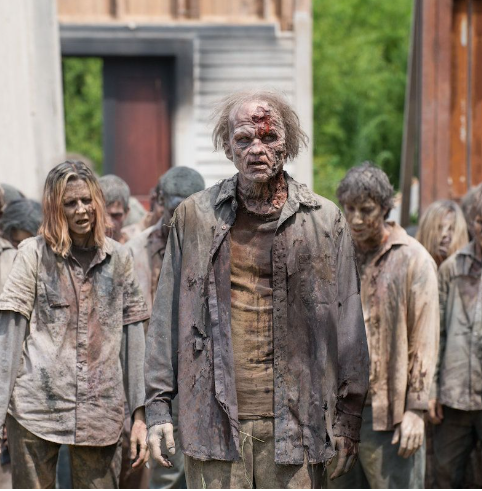

Un ataque zombie se puede modelar tambien con un modelo comartimental tipo SZR

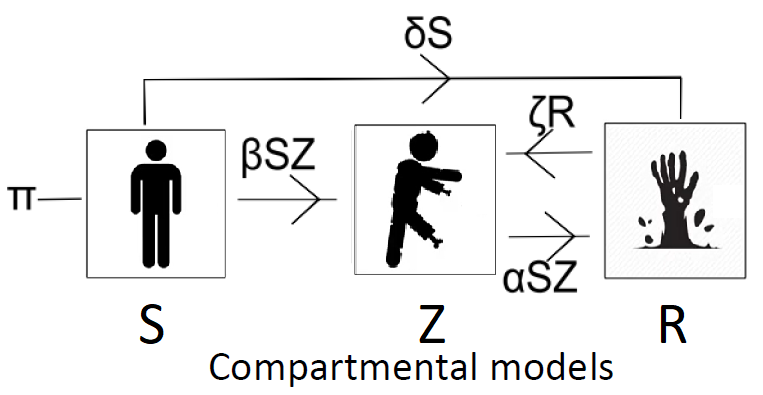

Con las siguientes ecuaciones


$$\dot{S} = \Pi -\beta S Z - \delta S \\
\dot{Z} = \beta S Z +\zeta R - \alpha S Z \\
\dot{R} = \delta S + \alpha S Z -\zeta R$$


Obtenido del artículo:

Munz, Philip, et al. "When zombies attack!: mathematical modelling of an outbreak of zombie infection." Infectious Disease Modelling Research Progress 4 (2009): 133-150

Los parámetros son los siguientes:

Parameters:

Π: Human birth rate (constant)

𝛽 : Rate of humans infected by Zombies (converted)

𝛿: Death rate of humans (not related to zombie attack)

𝜁: Cadaver to zombie conversión rate

𝛼: Rate of Zombies murdered by Humans

**Programa principal**

Primero debemos definir el vector de tiempo: para ello discretizamos el intervalo de tiempo con el fin de hallar las soluciones numéricas de esta ecuación para una condición inicial particular que nos será facilitada. Vamos a discretizar el intervalo [0,10] días, con un paso de 0.2.

%Tiempo (days)
tfin=20; dt=0.2; 
tspan = 0:dt:tfin;

Definimos los parámetros que en este caso vamos a pasarle a la función. Y los guardamos en el vector `params.` Hay que tener en cuenta el orden en el que guardamos los parámetros en el vector `params, `tiene que ser el mismo con el que se recuperan dentro de la función (al final del documento).

% Parámetros:
p = 20;
b = 1.9;
d = 0.01;
z = 1;
a = 10;
params=[p,b,d,z,a];

y las condiciones iniciales

% Condiciones iniciales
S0 = 20; %Condicion inicial de Susceptibles
Z0 = 0; %Cond. Inc. de Zombies
R0 = 0; %Cond. Inic. de Rem.
x0=[S0 Z0 R0];
% Tolerancias ode45
options=odeset('RelTol',1e-6,'Stats','off');

Finalmente, resolvemos la ecuación (simulamos) con el comando ode. 

%Llamada solver ode45
[t,X] = ode23s(@(t,x) modelo_SZR(t,x,params),tspan,x0,options);


Finalmente, representamos gráficamente la solución.

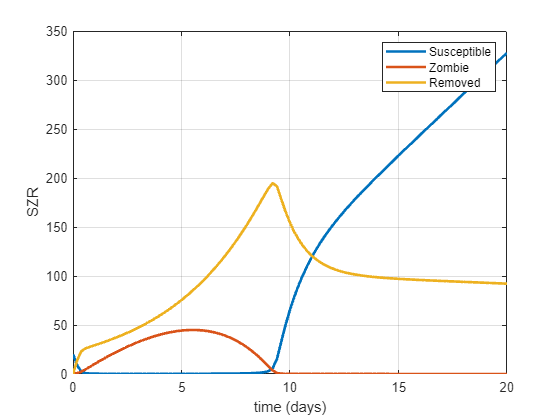

%Graficar respuesta modelo
figure;
plot(t,X,'LineWidth',2); grid on;
xlabel('time (days)'); ylabel('SZR');
legend('Susceptible','Zombie','Removed');

#### Definicion del modelo/ecuación ODE como una función

Definimos ahora una función que nos de el término derecho de las ecuaciones. Ésta expresión será evaluada en un instante $t$ y tomando un valor $x$, con los parámetros dados `parameters`. Esta función nos sirve para tratar algunas cuestiones a la hora de definir funciones. Como podéis ver a esta función se le pasa:

* El valor $t$ en el que es evaluada,

* el valor de $x$ donde es evaluado x

* los parámetros que nos permiten definir la ecuación

**Modelo ODE**

function [dx_dt]= modelo_SZR(t,x,params)
% Model parameters:
%params=[p,b,d,z,a];
p= params(1,1);
b= params(1,2);
d= params(1,3);
z= params(4);
a= params(5);
% Define the variables
S = x(1);
Z = x(2);
R = x(3);
%Define the equations
dS =  p               - b .* S .* Z           - d .* S;

dZ =  b .* S  .* Z    + z .* R                - a .* S .* Z;

dR =  d .* S          - z .* R                + a .* S .* Z;
%Collect the derivatives in one vector
dx_dt = [dZ; dS; dR];

end